clear 
k1 = 15;
k2 = 50;
L1 = 1;

g  =9.81;
m1 = 5;
m2 = 10;

% x0 = 0;
% y0 = -1.5;

x0 = 0;
y0 = -2;

syms t real
n = 2;

% Generalized coordinates, velocity, acceleration
q      = sym('q_'     ,[n 1],'real'); 
q_dot  = sym('q_dot_' ,[n 1],'real');
q_ddot = sym('q_ddot_',[n 1],'real');
x = q(1); th = q(2);

% Returns the time derivative
ddt = @(z) jacobian(z, [t ; q ; q_dot])*[1 ; q_dot ; q_ddot];

% Takes force F at r and transforms to generalized force 
F2Q = @(F,r) jacobian(r, q)'*F;

a = sym('a',[3 1],'real');
b = sym('b',[3 1],'real');
cross_mat = matlabFunction(jacobian(cross(a,b),b),'vars',{a});

R_ang_ax = @(ax, ang) expm(cross_mat(ax*ang));
R1 = @(ang) R_ang_ax(ang,[1 0 0]');
R2 = @(ang) R_ang_ax(ang,[0 1 0]');
R3 = @(ang) R_ang_ax(ang,[0 0 1]');

i_hat = [1 0 0]';
j_hat = [0 1 0]';
k_hat = [0 0 1]';
e1 = R3(th)*(-j_hat);



### 1. Kinematics and Keypoints

rA = x*i_hat;
rB = rA + L1*e1;
vA = ddt(rA);
vB = ddt(rB);

rB_fun = matlabFunction(rB, 'vars',{q});

spring_dr = y0*j_hat + x0*i_hat - rB;

V = m2*g*rB(2) + 1/2*k1*x^2 + 1/2*k2*spring_dr'*spring_dr;

T = 1/2*m1*vA'*vA + 1/2*m2*vB'*vB;

### 2. Find Equilibria and Check Stability


gradV = simplify(gradient(V,q));
hessV = hessian(V,q);

q_eq = [0 0]';
%q_eq = [.4497 1.1564]';

% Compute the hessian of the potential function
K_eq = double( subs(hessV,q,q_eq) ) ;

eig(K_eq)

ans =    48.3100
  214.7900


### **3. Modal Analysis**

M = hessian(T,q_dot); % Mass Matrix
M_eq = double( subs(M, q, q_eq) ) ;

[Modes, Eigs] = eig(M_eq\K_eq)

Modes =    -0.9990    0.5488
    0.0443   -0.8359


Eigs =     4.3130         0
         0   48.1170



Natural_Freqs = sqrt(diag(Eigs))

Natural_Freqs =     2.0768
    6.9366


### **4. Equations of Motion and First-Order ODEs**

L = T-V;
Qnc = F2Q(-20*vA, rA) + F2Q(-20*vB, rB); %[0 0]';
Qnc = [0 ; 0];
eom = ddt(gradient(L,q_dot)) - gradient(L,q)-Qnc;
q_ddot_eom = solve(eom, q_ddot);

X = [q; q_dot]; % State Space for simulation
X_dot = simplify([q_dot ; q_ddot_eom.q_ddot_1 ; q_ddot_eom.q_ddot_2 ]); % First order ODEs to simulate

### 5. Simulation

dyn = matlabFunction(X_dot, 'vars',{t, [q ; q_dot]});

q0 = q_eq+Modes(:,2)*.1; % Initial Conditions

tf = 10;

sol = ode45(dyn, [0 tf],  [q0 ; 0 ; 0] );

%qf = sol.y(1:2,end)


**Simulation Visualization**

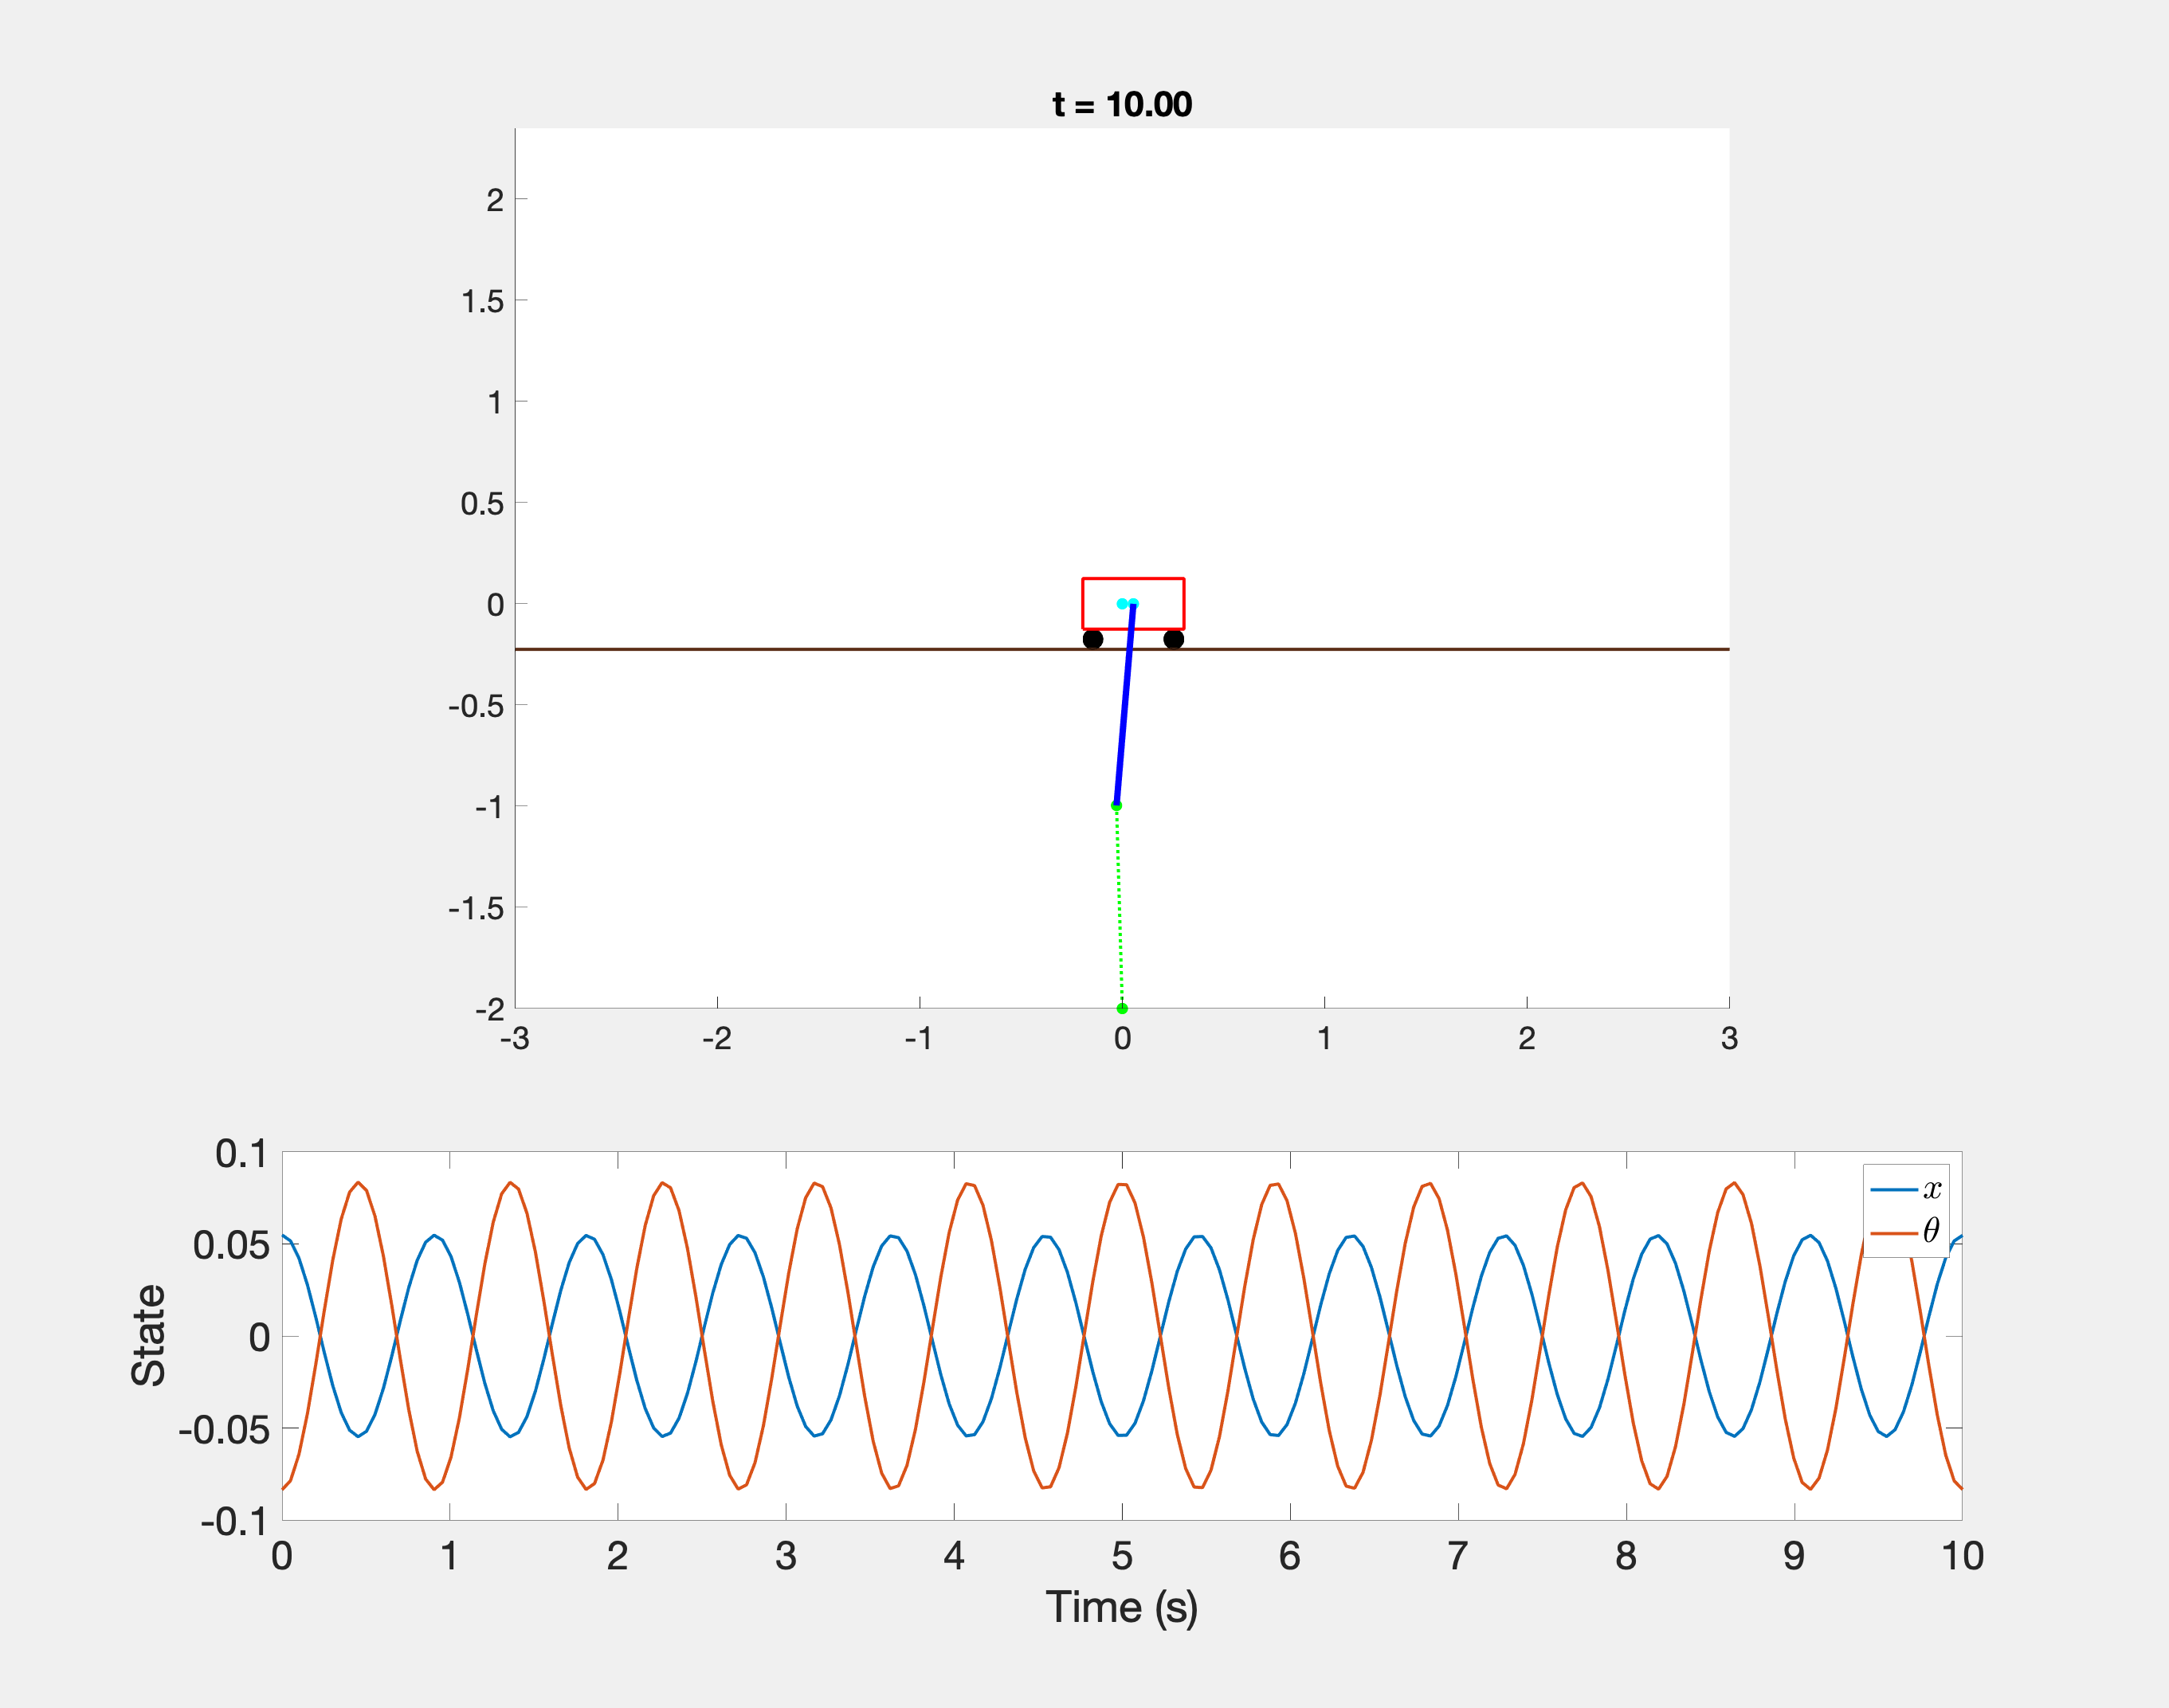



t_plot = linspace(0,tf,200);
state_plot = deval(sol, t_plot);

figure(2);
clf;
set(gcf,'Visible','on')
subplot(3,1,[3])
plot(t_plot, state_plot(1:2,:),'LineWidth',2);
set(gca,'FontSize',25);
l = legend('$x$','$\theta$');
l.Interpreter = 'Latex';
xlabel('Time (s)');
ylabel('State')

subplot(3, 1, [1 2])
anim_params.slow_mo = 1;
anim_params.frame_rate = 30;

length_val_pole = L1;
x = [0 0 0 0];
% Plotting
r_whl = .05;
h_car = .25;
w_car = .5;

set(gca,'FontSize',20);


ground_frame = hgtransform(gca);
ground_frame.Matrix = makehgtform('translate',-[0 2*r_whl+ h_car/2 0]);
ground = plot(ground_frame, [-3 3],[0 0],'k','LineWidth',2);
ground.Color = [92 47 24]/255;

frame0 = hgtransform(ground_frame);
frame0.Matrix = makehgtform('translate',[0 2*r_whl+ h_car/2 0]);
frame1 = hgtransform(frame0);
frame2 = hgtransform(frame1);
th_whl = linspace(0,2*pi,20);
fill(frame1,cos(th_whl)*r_whl - w_car/2+r_whl,sin(th_whl)*r_whl-h_car/2-r_whl,'k');
fill(frame1,cos(th_whl)*r_whl + w_car/2-r_whl,sin(th_whl)*r_whl-h_car/2-r_whl,'k');
plot(frame1,[-1 1 1 -1 -1]*w_car/2, [-1 -1 1 1 -1]*h_car/2,'r','LineWidth',2);
plot3(frame2,[0 0], [0 -length_val_pole],[0.01 0.01] ,'b','LineWidth',4);

axis equal
axis([-3 3 -2*length_val_pole 2*length_val_pole+h_car+2*r_whl]);

h_title = title('t=0');
hold on

dt = 1e-3;

tic 
dt_anim = 1 / (anim_params.slow_mo * anim_params.frame_rate);
next_anim = 0;

view([0 90])

h_sp1 = plot(gca, [0],[0],'g:.','LineWidth',2,'MarkerSize',20);
h_sp2 = plot(gca, [0],[0],'c:.','LineWidth',2,'MarkerSize',20);


for t_sim = 0:dt:sol.x(end)
    xx = deval(sol, t_sim);
    rB_now = rB_fun(xx(1:2));
    
    if t_sim >= next_anim
        h_title.String = ['t = ' sprintf('%.2f',t_sim)];
        
        h_sp1.XData = [rB_now(1) x0]';
        h_sp1.YData = [rB_now(2) y0]';
        h_sp2.XData = [0 xx(1)]';
        h_sp2.YData = [0 0]';
        frame1.Matrix = makehgtform('translate',[xx(1) 0 0]);
        frame2.Matrix = makehgtform('zrotate',xx(2));

        pause( t_sim*anim_params.slow_mo - toc )
        next_anim = t_sim + dt_anim;
    end

end